# Sintonía de un controlador PID

## Método: Ubicación de polos

Ejemplo:


$$\mathrm{Gp}\left(s\right)=\frac{6}{s^2 +0\ldotp 5s+1}$$


Requerimientsos del sistema de control en LC


$$\begin{array}{l}
M_p <0\ldotp 1\\
t_{{\mathrm{ss}}_{\mathrm{LC}} } <0\ldotp 5t_{{\mathrm{ss}}_{\mathrm{LA}} } 
\end{array}$$


close all
clear all

s = tf('s');
Gps = 6 / (s^2 + 0.5 * s + 1)

Gps =
 
         6
  ---------------
  s^2 + 0.5 s + 1
 
Continuous-time transfer function.
Model Properties


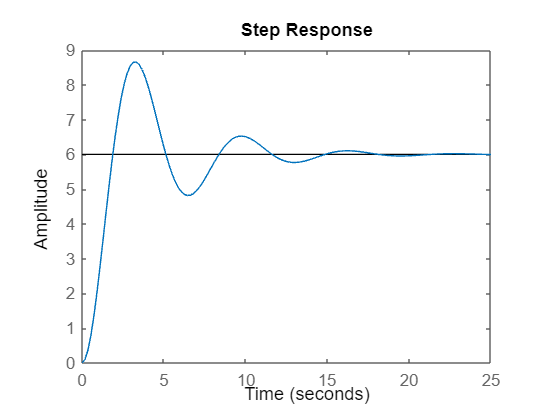

step(Gps)


syms z
MpLA = (8.66-6) / 6; % leido de la grafica
z = double(vpasolve(exp(-(pi*z)/sqrt(1-z^2))==MpLA,z));
tp = 3.32; % leido de la grafica
wn = pi/(tp*sqrt(1-z^2));
tssLA = pi / (z*wn);


$$\begin{array}{l}
M_p =e^{-\frac{\zeta_{\mathrm{LCr}} \pi }{\sqrt{\left(1-{\zeta_{\mathrm{LCr}} }^2 \right)}}\;} \\
t_{{\mathrm{ss}}_{\mathrm{LCr}} } =\frac{\pi }{\zeta_{\mathrm{LCr}} \omega_{n_{\mathrm{LCr}} } }
\end{array}$$


Mp = 0.1;
syms zr
zr = double(vpasolve(exp(-(pi*zr)/sqrt(1-zr^2))==Mp,zr))

zr = 0.5912

tssLC = 0.5*tssLA;
wnr = pi/(tssLC*zr)

wnr = 0.8289

alpha = 2*zr*wnr

alpha = 0.9800


%%% Calculo de PID continuo %%%
syms Kp Taud Taui
EQ1_TEO = 0.5 + 6*Kp*Taud;
EQ2_TEO = 1 + 6*Kp;
EQ3_TEO = 6*Kp/Taui;

EQ1_REQ = 2*zr*wnr + alpha;
EQ2_REQ = wnr^2 + 2*alpha*zr*wnr;
EQ3_REQ = alpha*wnr^2;

PID = vpasolve([EQ1_TEO==EQ1_REQ,EQ2_TEO==EQ2_REQ,...
    EQ3_TEO==EQ3_REQ],[Kp, Taud, Taui]);
Kp = double(PID.Kp)

Kp = 0.1079

Taud = double(PID.Taud)

Taud = 2.2546

Taui = double(PID.Taui)

Taui = 0.9617


T = 0.5; % sampling time
Kpz = Kp - (Kp*T)/(2*Taui)

Kpz = 0.0799

Kiz = Kp*T/Taui

Kiz = 0.0561

Kdz = Kp*Taud/T

Kdz = 0.4867


Gpz = c2d(Gps,T)

Gpz =
 
    0.6772 z + 0.6226
  ----------------------
  z^2 - 1.562 z + 0.7788
 
Sample time: 0.5 seconds
Discrete-time transfer function.
Model Properties


Gpz_num = Gpz.Numerator{1,1};
Gpz_den = Gpz.Denominator{1,1};